%5/4/24: ALTERED KNOT FUNCTION TO CONSIDER INTITAL T AFTER INTERRUPT AND
%NOT REVERT TO ZERO - USING PRANGE = PMAX-MIN
%6/4/23: WARNING: All values using order to locate knot vectors in
%corrector stages are entered MANUALLY - assumes snap: k=3, jerk: k=4, etc

%FUNCTIONAL STEPS
% 1.Spline and derivatives for original path is made
% 2.Interrupt pauses path following and 'snapshots' localisation
% 3.New target objective is inputted
% 4.Direction of motion is used to make a 'predictor'
% 5.Predictor is used to make a rough estimate of the new path
% 6.New path evaluated to the 4th derivative
% 7.'Snapshot' conditions are applied to the 4th derivative
% 8.Curve is then integrated with the initial conditions applied
% 9.Repeated until positional curve is found
% 10.Curves have initial conditions applied but no final conditions
% 11.'Corrector' points cancel the offset down to the desired final states
% 12.Correctors also limit positional magnitude to circular turn radius
% 13.Correctors are calculated from poisition to snap (downwards)
% 14.Integral points are then re-evaluated after the correctors (upwards)
% 15.These points will all cancel to zero, except position->newtarget
% 16.Inital clamps are added with additinal knots
% 17.Excess zeros and knots are then truncated
% 18.The curves are re-evaluated using the corrected control point sets


%INITIAL SPLINE AND DERIVATIVES
clear
targets = [0,0; 50,100; 100,0];
pmin = 0;
pmax = 5;
pstep = 0.01;
[FullMAT, CPMAT, knotMAT] = PathPlanner(targets,pmin,pmax,pstep);
N = height(CPMAT);
CP = CPMAT(:,1:2);
VCP = CPMAT(1:(N-1),3:4);
ACP = CPMAT(1:(N-2),5:6);
JCP = CPMAT(1:(N-3),7:8);
SCP = CPMAT(1:(N-4),9:10);
PosMAT = [FullMAT(:,1), FullMAT(:,2)];
VelMAT = [FullMAT(:,3), FullMAT(:,4)];
AccMAT = [FullMAT(:,5), FullMAT(:,6)];
JerkMAT = [FullMAT(:,7), FullMAT(:,8)];
SnapMAT = [FullMAT(:,9), FullMAT(:,10)];
BearingMAT = [FullMAT(:,11), FullMAT(:,12), FullMAT(:,13)];

%PAUSE LOCATION
%Pause/Interrupt
len = length(PosMAT);
PFact = 9/16;
Pauseloc = round(PFact*len);
Pauseloc2 = Pauseloc + round(len*PFact/4);
Hold = [PosMAT(Pauseloc,:); VelMAT(Pauseloc,:); AccMAT(Pauseloc,:); JerkMAT(Pauseloc,:); SnapMAT(Pauseloc,:)];
HoldRot = [BearingMAT(Pauseloc,:)];

%NEW TARGET
NewTarg = [120,40];

%DIRECTION OF MOTION
%TurnRad = magnitude of velocity * turn time (here 2 seconds)
TurnRadius = sqrt(Hold(2,1)^2+Hold(2,2)^2)*2;
Bearing = 2*pi*HoldRot(1,2)/360;
sect = HoldRot(1,3);
if sect == 1
    PredExt = [TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end
if sect == 2
    PredExt = [TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end
if sect == 3
    PredExt = [TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end
if sect == 4
    PredExt = [-TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end

%PREDICTOR
Predictor = [(Hold(1,1) + PredExt(1,1)), (Hold(1,2)+PredExt(1,2))];

%NEW TARGET POINTS
NewTargets = [Hold(1,1),Hold(1,2);Predictor; NewTarg];

%TIME EXTENSION
pmin = Pauseloc*pstep;
pmax = pmax+3;

%REPLAN
[RePlanMAT, ReplanCPMAT, ReplanknotMAT] = PathPlanner(NewTargets,pmin, pmax, pstep);
reN = height(ReplanCPMAT);
reknN = length(ReplanknotMAT);
reCP = ReplanCPMAT(:,1:2);
reVCP = ReplanCPMAT(1:(N-1),3:4);
reACP = ReplanCPMAT(1:(N-2),5:6);
reJCP = ReplanCPMAT(1:(N-3),7:8);
reSCP = ReplanCPMAT(1:(N-4),9:10);
%PLOT
%plot(RePlanMAT(:,1), RePlanMAT(:,2))
%hold on
%scatter(reCP(:,1), reCP(:,2), 160, 'X', 'red')
%hold off

%SNAP MAP
%plot(RePlanMAT(:,9), RePlanMAT(:,10))
%hold on
%scatter(reSCP(:,1), reSCP(:,2), 160, 'X', 'red')
%hold off

%Spline Setup
order = 3;
validpmin = ReplanknotMAT(1, 7);
validpmax = ReplanknotMAT(1, length(ReplanknotMAT)-6);
sknot = ReplanknotMAT(5, 1:(reknN-8));

%ADJUST SNAP
SN = height(reSCP);
reSCP(1,:) = Hold(5,:);
reSCP(2,:) = Hold(5,:);
NewSnap = evaluate(reSCP, pmin, pstep, pmax, validpmin, validpmax, sknot, order);
%plot(NewSnap(:,1), NewSnap(:,2))
%hold on
%scatter(reSCP(:,1), reSCP(:,2), 160, 'X', 'red')
%hold off

%INTEGRATION
%Intitial Conditions
C = Hold(1,:);
CV = Hold(2,:);
CA = Hold(3,:);
CJ = Hold(4,:);
%Integrators
ijknot = Ikn(sknot, pstep);
iJCP = ICP(reSCP, ijknot, order, CJ);
order = order + 1;
iJMAT = evaluate(iJCP, pmin, pstep, pmax, validpmin, validpmax, ijknot, order);
%integrate for Acc
iaknot = Ikn(ijknot, pstep);
iACP = ICP(iJCP, iaknot, order, CA);
order = order + 1;
iAMAT = evaluate(iACP, pmin, pstep, pmax, validpmin, validpmax, iaknot, order);
%integrate for Vel
ivknot = Ikn(iaknot, pstep);
iVCP = ICP(iACP, ivknot, order, CV);
order = order + 1;
iVMAT = evaluate(iVCP, pmin, pstep, pmax, validpmin, validpmax, ivknot, order);
%integrate for Pos
iknot = Ikn(ivknot, pstep);
iCP = ICP(iVCP, iknot, order, C);
order = order + 1;
iPMAT = evaluate(iCP, pmin, pstep, pmax, validpmin, validpmax, iknot, order);

%MAGNITUDE PASS
N = length(iCP);
MagFactor = 2;
magMax = MagFactor*sqrt((NewTarg(1,1)-iCP(1,1))^2+(NewTarg(1,2)-iCP(1,2))^2);
for i = 1:1:N
    mag = sqrt((NewTarg(1,1)-iCP(i,1))^2+(NewTarg(1,1)-iCP(i,2))^2);
    if mag > magMax
        M = i-1;
        break
    end
    if i == N
        disp("ERROR: Magnitude Limit not reached")
    end
end

%CORRECTOR PASS
%Velocity Corrector
iVCP(M, 1) = -(NewTarg(1,1)-iCP(M,1))*6/(iknot(M+1)-iknot(M+7));
iVCP(M, 2) = -(NewTarg(1,2)-iCP(M,2))*6/(iknot(M+1)-iknot(M+7));
iVCP = [iVCP; 0,0];
%Acceleration Corrector
iACP(M, 1) = -(0-iVCP(M,1))*5/(ivknot(M+1)-ivknot(M+6));
iACP(M, 2) = -(0-iVCP(M,2))*5/(ivknot(M+1)-ivknot(M+6));
iACP = [iACP; 0,0];
%Jerk Corrector
iJCP(M, 1) = -(0-iACP(M,1))*4/(iaknot(M+1)-iaknot(M+5));
iJCP(M, 2) = -(0-iACP(M,2))*4/(iaknot(M+1)-iaknot(M+5));
iJCP = [iJCP; 0,0];
%Snap Corrector
reSCP(M, 1) = -(0-iJCP(M,1))*3/(ijknot(M+1)-ijknot(M+4));
reSCP(M, 2) = -(0-iJCP(M,2))*3/(ijknot(M+1)-ijknot(M+4));
for i = M+1:1:height(reSCP)
    reSCP(i,1) = 0;
    reSCP(i,2) = 0;
end
reSCP = [reSCP; 0,0];

%RE-INTEGRAL PASS
%Snap Correction
nkn = length(sknot);
sknot = [sknot, sknot(nkn)+pstep];
%Reintegration
order = 3;
[iJCP, ijknot] = corrector(reSCP, iJCP, ijknot, pstep, M, order);
order = 4;
[iACP, iaknot] = corrector(iJCP, iACP, iaknot, pstep, M, order);
order = 5;
[iVCP, ivknot] = corrector(iACP, iVCP, ivknot, pstep, M, order);
order = 6;
[iCP, iknot] = corrector(iVCP, iCP, iknot, pstep, M, order);
%Initial Clamp Extension
order = 3;
[reSCP, sknot] = extended(reSCP, sknot, order, pstep)

reSCP =   168.2193  674.7064
  168.2193  674.7064
 -493.4358 -232.3999
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


sknot =     2.7900    2.8000    2.8100    3.5000    4.2500    5.0000    5.7500    6.5000    7.2500    7.9400    7.9500    7.9600    7.9700


order = 4;
[iJCP, ijknot] = extended(iJCP, ijknot, order, pstep);
order = 5;
[iACP, iaknot] = extended(iACP, iaknot, order, pstep);
order = 6;
[iVCP, ivknot] = extended(iVCP, ivknot, order, pstep);
order = 7;
[iCP, iknot] = extended(iCP, iknot, order, pstep);
%Truncation
order = 3;
ref = [0,0];
[reSCP, sknot] = truncated(reSCP, sknot, order, ref, pstep)

reSCP =   168.2193  674.7064
  168.2193  674.7064
 -493.4358 -232.3999
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


sknot =     2.7900    2.8000    2.8100    3.5000    4.2500    5.0000    5.7500    6.5000    7.2500    7.9400    7.9500    7.9600


order = 4;
[iJCP, ijknot] = truncated(iJCP, ijknot, order, ref, pstep)

iJCP =  -104.3725  341.1073
 -104.3725  341.1073
 -104.3725  341.1073
  -64.5606  500.7878
  360.2081  169.6519
         0         0
         0         0
         0         0
         0         0
         0         0


ijknot =     2.7700    2.7800    2.7900    2.8000    2.8100    3.5000    4.2500    5.0000    5.7500    6.5000    7.2500    7.9400    7.9500    7.9600    7.9700    7.9800


order = 5;
[iACP, iaknot] = truncated(iACP, iaknot, order, ref, pstep)

iACP =   -36.3583 -101.7514
  -36.3583 -101.7514
  -36.3583 -101.7514
  -36.3583 -101.7514
  -55.1454  -40.3521
 -198.1145  -93.3086
         0         0
         0         0
         0         0
         0         0


iaknot =     2.7500    2.7600    2.7700    2.7800    2.7900    2.8000    2.8100    3.5000    4.2500    5.0000    5.7500    6.5000    7.2500    7.9400    7.9500    7.9600    7.9700    7.9800    7.9900


order = 6;
[iVCP, ivknot] = truncated(iVCP, ivknot, order, ref, pstep)

iVCP =    56.4011  -41.5908
   56.4011  -41.5908
   56.4011  -41.5908
   56.4011  -41.5908
   56.4011  -41.5908
   51.0928  -56.4465
   87.5666   41.2424
         0         0
         0         0
         0         0


ivknot =     2.7400    2.7500    2.7600    2.7700    2.7800    2.7900    2.8000    2.8100    3.5000    4.2500    5.0000    5.7500    6.5000    7.2500    7.9400    7.9500    7.9600    7.9700    7.9800    7.9900    8.0000    8.0100


order = 7;
ref = [120,40];
[iCP, iknot] = truncated(iCP, iknot, order, ref, pstep)

iCP =    68.0413   43.7933
   68.0413   43.7933
   68.0413   43.7933
   68.0413   43.7933
   68.0413   43.7933
   68.0413   43.7933
   74.9975   38.6638
   87.6004   24.7403
  120.0000   40.0000
  120.0000   40.0000


iknot =     2.7200    2.7300    2.7400    2.7500    2.7600    2.7700    2.7800    2.7900    2.8000    2.8100    3.5000    4.2500    5.0000    5.7500    6.5000    7.2500    7.9400    7.9500    7.9600    7.9700    7.9800    7.9900    8.0000    8.0100    8.0200


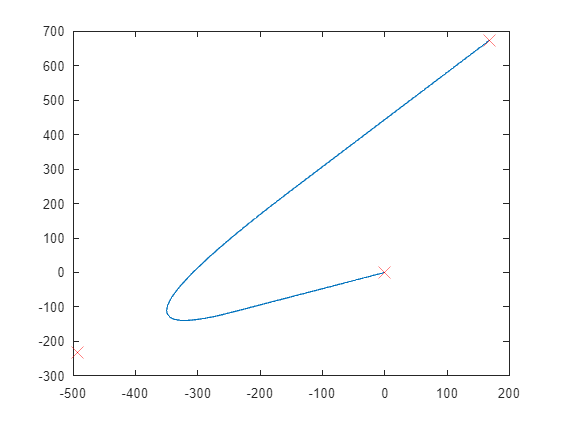


%Evaluate corrected Splines
order = 3;
cSnapMAT = evaluate(reSCP, pmin, pstep, pmax, validpmin, validpmax, sknot, order);
order = 4;
cJerkMAT = evaluate(iJCP, pmin, pstep, pmax, validpmin, validpmax, ijknot, order);
order = 5;
cAccMAT = evaluate(iACP, pmin, pstep, pmax, validpmin, validpmax, iaknot, order);
order = 6;
cVelMAT = evaluate(iVCP, pmin, pstep, pmax, validpmin, validpmax, ivknot, order);
order = 7;
cPosMAT = evaluate(iCP, pmin, pstep, pmax, validpmin, validpmax, iknot, order);
%Display
plot(cSnapMAT(:,1), cSnapMAT(:,2))
hold on
scatter(reSCP(:,1), reSCP(:,2), 160, 'X', 'red')
hold off

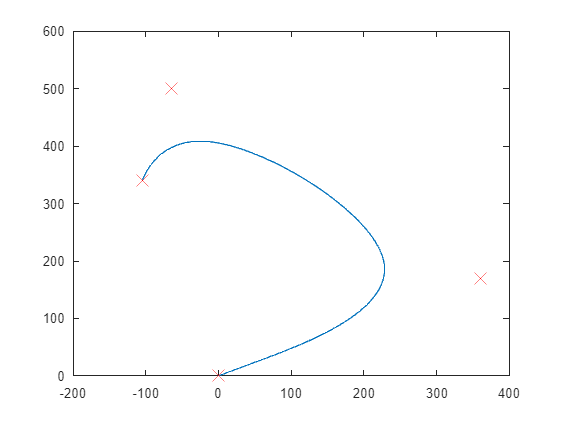

plot(cJerkMAT(:,1), cJerkMAT(:,2))
hold on
scatter(iJCP(:,1), iJCP(:,2), 160, 'X', 'red')
hold off

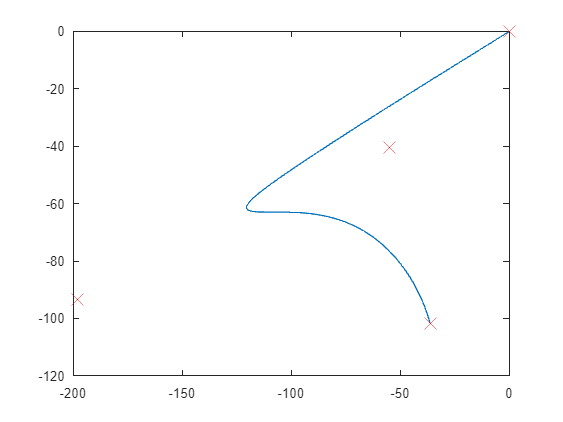

plot(cAccMAT(:,1), cAccMAT(:,2))
hold on
scatter(iACP(:,1), iACP(:,2), 160, 'X', 'red')
hold off

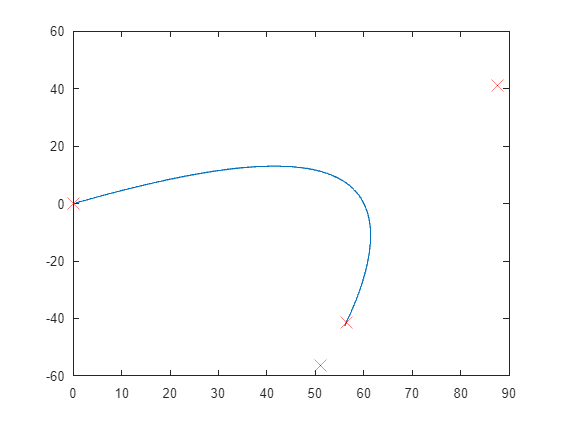

plot(cVelMAT(:,1), cVelMAT(:,2))
hold on
scatter(iVCP(:,1), iVCP(:,2), 160, 'X', 'red')
hold off

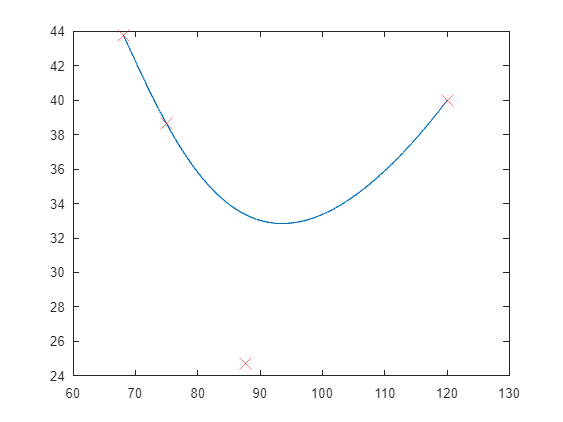

plot(cPosMAT(:,1), cPosMAT(:,2))
hold on
scatter(iCP(:,1), iCP(:,2), 160, 'X', 'red')
hold off

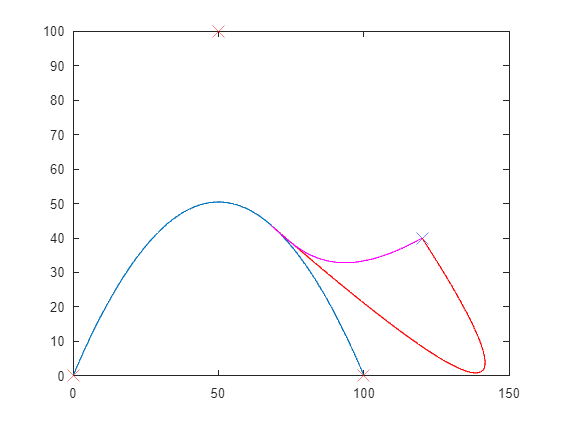


plot(PosMAT(:,1), PosMAT(:,2))
hold on
scatter(CP(:,1), CP(:,2), 160, 'X', 'red')
scatter(NewTarg(1,1), NewTarg(1,2), 160, 'X', 'blue')
plot(RePlanMAT(:,1), RePlanMAT(:,2), 'red')
plot(cPosMAT(:,1), cPosMAT(:,2), 'magenta')
hold off

function [FullMAT, CPMAT, knotMAT] = PathPlanner(targets, pmin, pmax ,pstep)
    order = 7;
    CP = points(targets, order);
    CPx = CP(:,1);
    CPy = CP(:,2);
    %Knot Vector
    knot = knotvect(CP, order, pmin, pmax, pstep);
    ksz = size(knot);
    validpmin = knot(1, order);
    validpmax = knot(1, (ksz(1,2)-order+1));
    NK2MAT = [];
    NK3MAT = [];
    NK4MAT = [];
    NK5MAT = [];
    NK6MAT = [];
    NK7MAT = [];
    pM1 = [];
    pM2 = [];
    pM3 = [];
    pM4 = [];
    pM5 = [];
    pM6 = [];
    %Initial Path Plan
    PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    order = 6;
    VCP = DCP(CP, knot, order);
    vknot = Dkn(knot);
    VelMAT = evaluate(VCP, pmin, pstep, pmax, validpmin, validpmax, vknot, order);
    order = 5;
    ACP = DCP(VCP, vknot, order);
    aknot = Dkn(vknot);
    AccMAT = evaluate(ACP, pmin, pstep, pmax, validpmin, validpmax, aknot, order);
    order = 4;
    JCP = DCP(ACP, aknot, order);
    jknot = Dkn(aknot);
    JerkMAT = evaluate(JCP, pmin, pstep, pmax, validpmin, validpmax, jknot, order);
    order = 3;
    SCP = DCP(JCP, jknot, order);
    sknot = Dkn(jknot);
    SnapMAT = evaluate(SCP, pmin, pstep, pmax, validpmin, validpmax, sknot, order);
    BearingMAT = direc(VelMAT);

    %Load all data into matrix for function return
    FullMAT = [PosMAT, VelMAT, AccMAT, JerkMAT, SnapMAT, BearingMAT];
    CPMAT = [CP, [VCP; 0,0], [ACP;0,0;0,0], [JCP;0,0;0,0;0,0], [SCP;0,0;0,0;0,0;0,0]];
    knotMAT = [knot; [vknot, 0, 0]; [aknot,0,0,0,0]; [jknot,0,0,0,0,0,0]; [sknot,0,0,0,0,0,0,0,0]];
end  
function pMAT = pMAT(p,knot,k)
        N = length(knot);
        pMAT = [];
        for i = 1:1:N-k
            pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
            pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
            Head = zeros(i-1,1);
            Foot = zeros(N-k-i,1);
            pvect = [Head; pconst1; pconst2; Foot];
            pMAT = [pMAT, pvect];
        end
end
function CP = points(targets, order)
        P = height(targets);
        rep = order - 1;
        CP = [];
        hold = [targets(1,1), targets(1,2)];
        for n = 1:1:rep
            CP = [CP; hold];
        end
        for i = 2:1:P-1
            hold = [targets(i,1), targets(i,2)];
            CP = [CP; hold];
        end
        hold = [targets(P,1), targets(P,2)];
        for k = 1:1:rep
            CP = [CP; hold];
        end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
        %ALTERED FUNCTION WITH P RANGE TO CONSIDER INITIAL TIME AFTER
        %INTERRUPT AND NOT REVERT TO ZERO
        sz = size(CP);
        P = sz(1,1);
        K = P + order;
        prange = pmax-pmin;
        Knot = pmin;
        for i = 1:1:order-1
            Knot = [Knot, pmin+i*pstep];
        end
        for i = 1:1:K-2*order
            Knot = [Knot, pmin+i*prange/(K-2*order+1)];
        end
        for i = 1:1:order
            Knot = [Knot, pmax-(order-i)*pstep];
        end
end
function NK1MAT = NK1MAT(p, knot)
        N = length(knot);
        NK1MAT = [];
        for i = 1:1:N-1
            lowkn = knot(i);
            highkn = knot(i+1);
            if lowkn<=p && p<highkn
                NK1MAT = [NK1MAT, 1];
            else
                NK1MAT = [NK1MAT, 0];
            end
        end
end
function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
        BSplineMAT = [];
        for p = pmin:pstep:pmax
            if p >= validpmin
                if p<=validpmax
                    k = 2;
                    NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                    k = 3;
                    NK3MAT = NK2MAT*pMAT(p, knot, k);
                    k = 4;
                    if order < k
                        Pos = NK3MAT*CP;
                    else
                        NK4MAT = NK3MAT*pMAT(p, knot, k);
                        k = 5;
                        if order < k
                            Pos = NK4MAT*CP;
                        else
                            NK5MAT = NK4MAT*pMAT(p, knot, k);
                            k = 6;
                            if order < k
                                Pos = NK5MAT*CP;
                            else
                                NK6MAT = NK5MAT*pMAT(p, knot, k);
                                k = 7;
                                if order < k
                                    Pos = NK6MAT*CP;
                                else
                                    NK7MAT = NK6MAT*pMAT(p, knot, k);
                                    Pos = NK7MAT*CP;
                                end
                            end
                        end
                    end
                    BSplineMAT = [BSplineMAT; Pos];
                end
            end
        end
end
function DP = DCP(CP, knot, k)
        n = length(CP);
        DP = [];
        for i = 1:1:n-1
            I = i+1;
            P1 = [CP(i,1),CP(i,2)];
            P2 = [CP(i+1,1),CP(i+1,2)];
            DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
            DP = [DP; DPnew];
        end
end
function DKnot = Dkn(knot)
        N = length(knot);
        DKnot = [];
        for i = 1:1:N-2
            DKnew = knot(i+1);
            DKnot = [DKnot, DKnew];
        end
end
function MagMAT = absBS(Pos)
        N = length(Pos.');
        MagMAT = [];
        for i = 1:1:N
            X = Pos(i,1);
            Y = Pos(i,2);
            abs = sqrt(X^2+Y^2);
            MagMAT = [MagMAT; i, abs];
        end
end
function bearingMAT = direc(Vel)
        N = length(Vel.');
        bearingMAT = [];
        for i = 1:1:N
            X = Vel(i,1);
            Y = Vel(i,2);
            vtan = (360*atan(X/Y))/(2*pi);
            if X >= 0 && Y >= 0
                dir = vtan;
                sect = 1;
            end
            if X >= 0 && Y < 0
                dir = 180 + vtan;
                sect = 2;
            end
            if X < 0 && Y >= 0
                dir = 360 + vtan;
                sect = 3;
            end
            if X < 0 && Y < 0
                dir = 180 + vtan;
                sect = 4;
            end
            bearingMAT = [bearingMAT; i, dir, sect];
        end
end

%%% INTEGRATOR FUNCTIONS

function IP = ICP(CP, knot, k, c)
    CPx = CP(:,1);
    CPy = CP(:,2);
    n = length(CP);
    IP1 = c;
    IP = IP1;
    for i = 1:1:n
        xhold = CPx(i);
        yhold = CPy(i);
        IP2x = xhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,1);
        IP2y = yhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,2);
        IP = [IP; IP2x, IP2y];
        IP1 = [IP2x, IP2y];
    end
end
function Iknot = Ikn(knot, pstep)
    n = length(knot);
    Iknot = knot(1)-pstep;
    for i = 1:1:n
        Iknot = [Iknot, knot(i)];
    end
    Iknot = [Iknot, knot(n)+pstep];
end
function [iP, iknot] = corrector(CP, iP, iknot, pstep, M, k)
    CPx = CP(:,1);
    CPy = CP(:,2);
    n = length(CP);
    IP1 = iP(M, :);
    for i = M:1:n
        xhold = CPx(i);
        yhold = CPy(i);
        IP2x = xhold*(iknot(i+1+k)-iknot(i+1))/k + IP1(1,1);
        IP2y = yhold*(iknot(i+1+k)-iknot(i+1))/k + IP1(1,2);
        IP2x = round(IP2x,4);
        IP2y = round(IP2y,4);
        iP(i+1, 1) = IP2x;
        iP(i+1, 2) = IP2y;
        IP1 = [IP2x, IP2y];
    end
    nkn = length(iknot);
    iknot = [iknot, iknot(nkn)+pstep];
end
function [CP, eknot] = extended(CP, knot, k, pstep)
    flip = -1;  
    eknot = knot;
    if k ~= 3
        for i = 1:1:k-2
            CP = [CP(1,1),CP(1,2);CP];
            if flip == -1
                hold = eknot(1)-pstep;
                eknot = [hold, eknot];
            else
                if flip == 1
                    hold = eknot(end)+pstep;
                    eknot = [eknot, hold];
                else
                    disp("FLIP ERROR -> Truncated Function");
                end
            end
            flip = flip*(-1);
        end
    end
end
function [tCP, tknot] = truncated(CP, knot, k, ref, pstep)
    n = height(CP);
    c = 0;
    refx = ref(1,1);
    refy = ref(1,2);
    %Find the clamp length
    for i = n:-1:1
        holdx = CP(i, 1);
        holdy = CP(i, 2);
        if holdx ~= refx
            break
        else
            if holdy ~= refy
                break
            else
                c = c+1;
            end
        end
    end
    %Difference between held and desired
    %%%ADDED 4 FROM ORIGINAL TO COMPENSATE FOR KNOT PROBLEM
    N = k-c+3;
    %If too many clamps, truncate, if not enough, extend.
    if N ~= 0
        if n+N > n
            tCP = CP;
            tknot = knot;
            flip = -1;
            %EXTENSION (POINTS AND KNOT)
            for i = 1:1:N
                tCP(i+n,1) = refx;
                tCP(i+n,2) = refy;
                if flip == -1
                    hold = tknot(1)-pstep;
                    tknot = [hold, tknot];
                else
                    if flip == 1
                        hold = tknot(end)+pstep;
                        tknot = [tknot, hold];
                    else
                        disp("FLIP ERROR -> Truncated Function");
                    end
                end
                flip = flip*(-1);
            end
        else
            %TRUNCATION (POINTS AND KNOT)
            for i = 1:1:n+N
                tCP(i,1) = CP(i,1);
                tCP(i,2) = CP(i,2);
            end
            tknot = knot;
            flip = -1;
            for i = 1:1:-N
                n = length(tknot);
                if flip == -1
                    tknot = tknot(1:n-1);
                else
                    if flip == 1
                        tknot = tknot(2:n);
                    else
                        disp("FLIP ERROR -> Truncated Function");
                    end
                end
                flip = flip*(-1);
            end
        end
    end
end